# gpryuiが動くかの確認

"ガウス過程と機械学習" のサンプルコード

clc 
clear
close all

curdir = pwd;
addpath(strcat(curdir, '/../../gpryui/'));
addpath(strcat(curdir, '/../../hara_functions/'))

tau = log(1);
sigma = log(1);
eta = log(0.1);
params = [tau, sigma, eta];

data = readmatrix('gpr.dat');
x_train = data(:, 1);
y_train = data(:, 2);

x = (-1:0.01:4)';

[K, Kinv] = kernelMatrix(x_train, params);

[y_reg_mu, y_reg_var] = gprNormal(x, x_train, y_train, params, Kinv);

two_sigma1 = y_reg_mu - 2 * sqrt(y_reg_var); two_sigma2 = y_reg_mu + 2 * sqrt(y_reg_var);

figname = "gprConfirmation"

figname = "gprConfirmation"

figure('Name', figname);
patch([x', fliplr(x')], [two_sigma1', fliplr(two_sigma2')], 'c')
hold on;
plot(x_train, y_train, 'bx', MarkerSize=20);
hold on;
plot(x, y_reg_mu, 'b-', Linewidth=2);
title(figname);

savename = strcat(figname, ".pdf")

savename = "gprConfirmation.pdf"

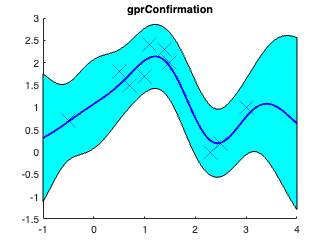

exportgraphics(gcf, savename);